# Mission Analysis Walkthrough — L1 disciplines

This live script computes the F-16A mission fuel with the **Level-1 (L1)** discipline models. It flies the Combat Air Patrol (CAP) profile. It shows how the aerodynamics, propulsion, and geometry models feed each mission segment.

Mission analysis threads the weight through an ordered list of segments. Each segment burns some fuel, so the weight drops from one segment to the next. The sum of the burns is the mission fuel.

Method reference: L1 uses constant historical weight fractions for the ground and climb legs (Roskam, *Airplane Design Part I*, Table 2.1). It uses the Breguet range and endurance equations for the cruise, dash, loiter, and combat legs. The lift-to-drag ratio comes from the aero object; the fuel consumption comes from the prop object.

This walkthrough does the following steps:

- it builds the L1 aerodynamics, propulsion, and geometry models

- it shows how the drag polar and the fuel consumption feed a cruise leg

- it flies the ten-segment CAP profile

- it reports the fuel burned by each segment

- it adds the reserve to get the total fuel

The coupled sizing loop solves for the takeoff weight that makes the fuel close. That loop is a separate pass. It is not shown here.

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("f16a_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "F16A"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/, examples/, and VnV/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
    addpath(genpath(fullfile(root, "VnV")));
end

## Build the L1 discipline models

The mission analysis needs three discipline objects. The aerodynamics object gives the drag polar. The propulsion object gives the fuel consumption. The geometry object gives the reference area and the engine count.

We fix the takeoff gross weight at Brandt's F-16A value, 31,377 lbf. In a full sizing run the loop would solve for this weight. Here we hold it fixed so the walkthrough is self-contained. The L1 geometry model estimates its wetted area from the takeoff weight, so we set `W_TO` on the geometry object as well.

aero = F16AeroL1(f16a_spec_path(1));
prop = F16PropL1(f16a_spec_path(1));
geom = F16GeomL1(f16a_spec_path(1), f16a_requirements_path());
W_TO = 31377;
geom.W_TO = W_TO;

## What the models produce for a cruise leg

A Breguet cruise leg needs three inputs: the true airspeed, the fuel consumption, and the lift-to-drag ratio. The airspeed comes from the atmosphere state. The fuel consumption comes from the prop object. The lift-to-drag ratio is built from the aero drag polar, the geometry reference area, and the current weight.

The lift coefficient in level flight is $ C_L = W/(q S) $. The drag coefficient is $ C_D = C_{D0} + K_1 C_L^2 + K_2 C_L $. The ratio $ L/D = C_L/C_D $. This example uses cruise at 40,000 ft and Mach 0.87, at a representative mid-cruise weight.

cruise   = AircraftState(40000, 0.87);
W_cruise = 0.90 * W_TO;
CL = W_cruise / (cruise.q * geom.get_S_ref());
polar = aero.drag_polar(cruise);
CD = polar.CD0 + polar.K1*CL^2 + polar.K2*CL;
LD = CL / CD;
cruiseLD = table([CL; CD; LD; cruise.V], 'VariableNames', "Value", 'RowNames', ...
    {'CL  lift coefficient', 'CD  drag coefficient', 'L/D  lift-to-drag', 'V  true airspeed [ft/s]'})

cruiseLD = 4×1 table
                                Value  
                               ________

    CL  lift coefficient        0.45359
    CD  drag coefficient       0.040025
    L/D  lift-to-drag            11.333
    V  true airspeed [ft/s]      842.23


The propulsion object returns the fuel consumption. At L1 it is categorical: cruise power above Mach 0.4 and loiter power below. The next table shows the cruise value and the loiter value.

loiter = AircraftState(10000, 0.31);
propSummary = table([prop.get_TSFC(cruise); prop.get_TSFC(loiter)], 'VariableNames', "TSFC_per_hr", ...
    'RowNames', {'cruise power (M0.87)', 'loiter power (M0.31)'})

propSummary = 2×1 table
                            TSFC_per_hr
                            ___________

    cruise power (M0.87)        0.8    
    loiter power (M0.31)        0.7    


The next table maps each model output to the place where it enters the mission.

## Build the mission

`MissionAnalysisL1.from_requirements` reads the CAP profile from `f16a_requirements.json`. It injects the aero, prop, and geom objects. The `"cap"` name selects the ten-segment profile.

mission = MissionAnalysisL1.from_requirements(aero, prop, geom, f16a_requirements_path(), "cap");

Each segment maps to one of three L1 segment classes. The choice depends on the segment type.

The Breguet range leg solves $ R = (V/c_t)(L/D)\ln(W_i/W_{i+1}) $ for the end weight. The Breguet endurance leg solves $ E = (1/c_t)(L/D)\ln(W_i/W_{i+1}) $ for the end weight.

## Run the mission and read the fuel by segment

`total_fuel` threads the weight through the segments. It returns the total fuel with reserve, plus a breakdown. The breakdown carries the fuel per segment, the weight after each segment, and the drivers `L/D` and `TSFC` on the legs that use them. The fixed-fraction legs show no `L/D` or `TSFC`, because they do not use them.

[W_fuel, bd] = mission.total_fuel(W_TO);
nSeg = numel(bd.names);
LD_seg = nan(nSeg,1); TSFC_seg = nan(nSeg,1);
for i = 1:nSeg
    d = bd.debug{i};
    if isfield(d, 'LD'),          LD_seg(i)   = d.LD;   end
    if isfield(d, 'TSFC_per_hr'), TSFC_seg(i) = d.TSFC_per_hr; end
end
segTable = table(bd.names(:), bd.fuel_lbf(:), bd.W_after(:), LD_seg, TSFC_seg, ...
    'VariableNames', ["Segment", "Fuel_lb", "Weight_after_lb", "L_over_D", "TSFC_per_hr"])

segTable = 10×5 table
     Segment     Fuel_lb    Weight_after_lb    L_over_D    TSFC_per_hr
    _________    _______    _______________    ________    ___________

    "Startup"    313.77          31063             NaN         NaN    
    "Taxi"       310.63          30753             NaN         NaN    
    "Takeoff"    307.53          30445             NaN         NaN    
    "Climb"      2131.2          28314             NaN         NaN    
    "Cruise"     751.31          27563          11.326         0.8    
    "Dash"       298.76          27264          3.9993         0.8    
    "Combat"     66.881          22797          10.857         0.8    
    "Cruise2"    745.86          22051          11.567         0.8    
    "Loiter"     553.69          21497          9.1756         0.7    
    "Landing"    107.49          21390             NaN         NaN    


## Fuel by segment

The bar chart shows where the fuel goes. Climb and the two cruise legs dominate the CAP mission.

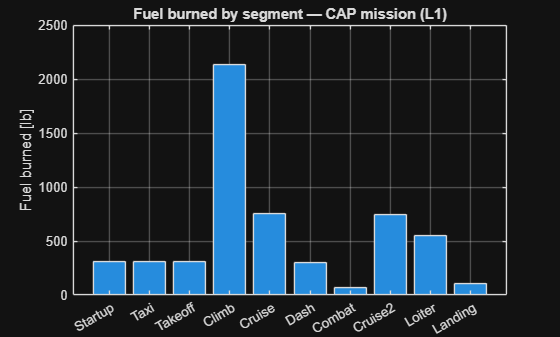

segCats = categorical(bd.names(:), bd.names(:));
bar(segCats, bd.fuel_lbf(:))
grid on
ylabel('Fuel burned [lb]')
title('Fuel burned by segment — CAP mission (L1)')

## Totals and reserve

The raw burn is the sum of the segment fuels. The total fuel adds a reserve fraction on top: $ W_{fuel} = W_{raw}(1 + f_{res}) $, with $ f_{res} = 0.06 $ for this profile (Roskam Part I, Eq. 2.14 to 2.15).

totals = table([bd.raw_burn; bd.reserve_fuel_fraction; W_fuel], 'VariableNames', "Value", 'RowNames', ...
    {'Raw burn (sum of segments) [lb]', 'Reserve fraction', 'Total fuel with reserve [lb]'})

totals = 3×1 table
                                       Value 
                                       ______

    Raw burn (sum of segments) [lb]    5587.1
    Reserve fraction                     0.06
    Total fuel with reserve [lb]       5922.3


## Summary

The L1 aerodynamics model set the `L/D` on the Breguet legs. The L1 propulsion model set the fuel consumption. The geometry model set the reference area and the engine count. The fixed-fraction legs used historical fractions instead. Together they gave the fuel burned by each segment and the total.

This run held the takeoff weight fixed. The coupled sizing loop instead solves for the takeoff weight that makes the fuel, the empty weight, and the payload add up. That loop is a separate pass and is not shown in this script.

To run the same mission at higher fidelity, open `mission_analysis_highfidelity_walkthrough.mlx`.